clear all, close all, clc

## HW03-02

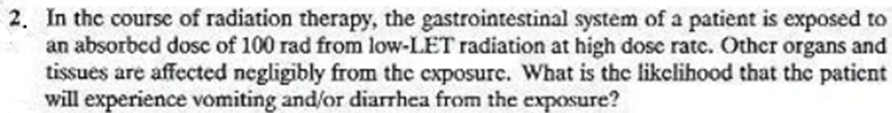

Given that

D = 100;            % dose; rad
D = D/100           % Gy

D = 1

Now, let's use the folloiwng table.

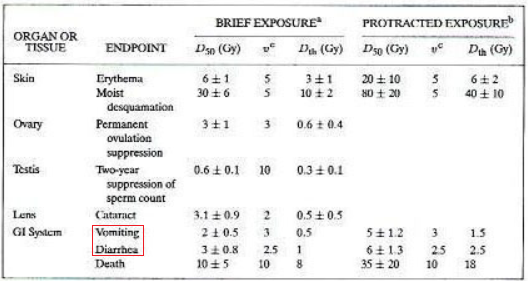

**Vomitting**

Herefrom, we get

D_50 = 2.0;             % dose eff, median; Gy
nu = 3;                 % shape factor

$H={\left(\frac{D}{D_{50} }\right)}^{\nu \;} \ln \left(2\right)$; $R=1-e^{-H}$

H = (D /D_50)^nu *log(2);   % hazard function
R = 1 - exp(-H)             % risk of vomitting

R = 0.0830

P_V = R*100                 % likelihood of vomitting; %

P_V = 8.2996

(Ans)

**Diarrhea**

D_50 = 3.0;                 % median effective absorbed dose; Gy
nu = 2.5;                   % shape factor
H = (D /D_50)^nu *log(2);   % hazard function
R = 1 - exp(-H)             % risk of diarrhea

R = 0.0435

P_D = R*100                 % likelihood of diarrhea; %

P_D = 4.3491

(Ans)

## **HW03-03**

 Given, it was whole-body dose and this - most prominently - kills bone-marrow cells, which becomes life threatening. Also, as given, supportive medical treatment was provided.

D = 5;          % absorbed dose; Gy

from the following Table 3.3 from the textbook, we get-

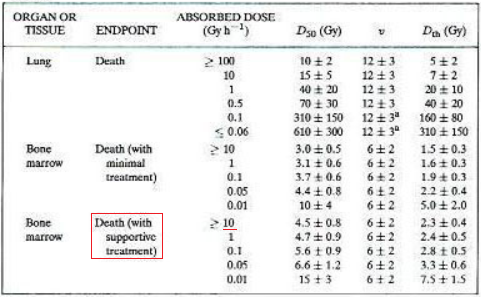

As, it was said, the dose was absorbed at high dose-rate, let's assume it is >= 10 Gy.h^-1. Now, let's find the middle value

D_50 = 4.5;                 % dose, 50 %tile; Gy 
nu = 6;                     % shape factor
H = (D /D_50)^nu *log(2);   % hazard function
R = 1 - exp(-H)             % risk of death

R = 0.7286

Now, let's calculate the lower bound of the probability

D_50 = 4.5 + 0.8;           % dose, 50 %tile; Gy
nu = 6 + 2;                 % shape factor
H = (D /D_50)^nu *log(2);   % hazard function
R = 1 - exp(-H)             % risk of death

R = 0.3527

(Ans)

Now, let's consider the upper bound of the probability

D_50 = 4.5 - 0.8;           % dose, 50 %tile; Gy
nu = 6 - 2;                 % shape factor
H = (D /D_50)^nu *log(2);   % hazard function
R = 1 - exp(-H)             % risk of death

R = 0.9009

(Ans)

## HW03-05

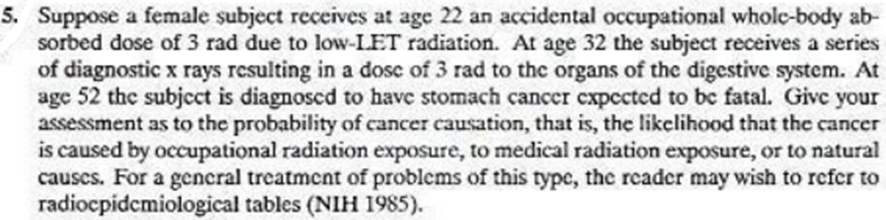

Given, for the occupational radiation exposure-

D = 3/100;          % dose; Gy
 Wt_d = 0.3;        % weighting f for digestive system
D = D *Wt_d;        % effective GI dose; Gy(Sv)
a0 = 22;            % age of exposure; y
a = 52;             % age of occurence of cancer; y
t = a - a0;         % latent period; y

Now, for digestive cancer, we know from the book eq(3.50), the follows-

 . Here, R is the relative risk.

g1 = 0.553;     % female
g2 = 0;         % for a0 <= 25;
R = 0.809*D *exp(g1 - g2)

R = 0.0127

(Ans)

Now, for the medical radiation exposure

D = 3/100;          % dose, Gy
a0 = 32;            % age of exposure 
a = 52;             % age of occurence of cancer
t = a - a0;         % latent period

So, here, to calculate R

g1 = 0.553;            % female
g2 = 0.198*(a0-25);    % for 25 <a0 <35;
R = 0.809*D *exp(g1 - g2)

R = 0.0106

So, it is seen from the estimation that, the relative risk of cancer-causation is higher for occupational exposure. So, we can conclude that- the woman could have contracted cancer at the age of 52- most likely - because of her occupational exposure at the age of 22.

(Ans)

## HW03-08

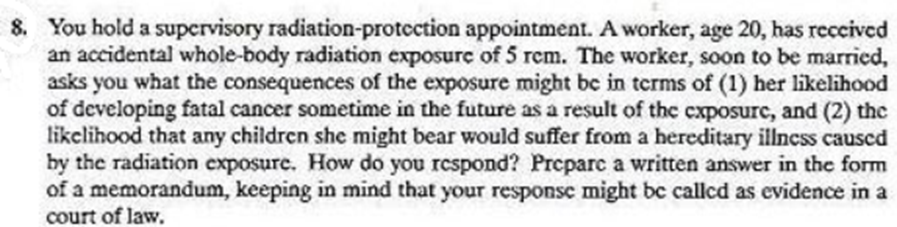

Given,

D = 5;          % W-body dose; rem
Wt = 1;         % W-body weighting factor
D = D/Wt;       % dose; rad
D = D/100       % dose; Gy

D = 0.0500

a0 = 20;        % age of exposure; y

Now, let's estimate the risk of cancers by estimating the Relative Risks regarding individual pathology

**Leukemia**

a = linspace(25,65,9)   % array of age; y

a =     25    30    35    40    45    50    55    60    65


t = a - a0              % latent periods; y

t =      5    10    15    20    25    30    35    40    45


Then, given a0 = 20

for i = 1:1:length(t)
    if t(i) <= 15
        g(i) = 4.885;
    elseif t(i) > 15 && t(i) <= 25
        g(i) = 2.380;
    else 
        g(i) = 2.380;
    end
    
    R_L(i) = (0.243*D + 0.271 *D^2).*exp(g(i));
end
R_L             % risk of leukemia 

R_L =     1.6970    1.6970    1.6970    0.1386    0.1386    0.1386    0.1386    0.1386    0.1386


**Respiratory Cancer**

De = D *2;          % using DREF of 2
g = 0.711;          % for female
R_r = 0.636*De *exp(-1.437*log(t./20) + g)      % risk of lung cancer

R_r =     0.9493    0.3506    0.1958    0.1295    0.0940    0.0723    0.0579    0.0478    0.0404


**Breast Cancer**

De = D*2;       % using DREF
g1 = 0;         % a0 > 15;
g2 = 0.0628;    % a0 > 15
    xp = g1 - 0.104*log(t/20) - 2.212*(log(t/20)).^2 - g2*(t-20);   % exponent term
R_b = 1.22*De *exp(xp)      % risk of breast cancer

R_b =     0.0052    0.0849    0.1433    0.1220    0.0780    0.0434    0.0224    0.0112    0.0054


**Digestive Cancer**

De = 2*D;
g1 = 0.553;     % for female
g2 = 0;         % for a0 < 25;
R_d = 0.809*De *exp(g1 - g2)        % rist of digestive cancer

R_d = 0.1406

**Other Cancers**

De = 2*D;
g = 0.0464*(a0 - 10);       % for a0 > 10
R_O = 1.22*De* exp(-g)      % risk of other cancer

R_O = 0.0767

**Genetic Risk**

D = 5;          % rem
D = D/100;      % Gy
 Wt = 0.2;      % wt-factor, gonad
De = D*Wt       % Sv

De = 0.0100

Let's use the following table from textbook-

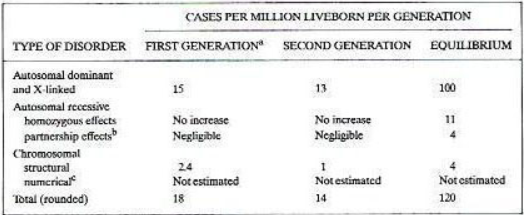

From this table, we have, for 10^6 people/0.01 Gy(Sv) for gonad - if exposed to radiation (0.01 Gy), among them- 120 of future generation might develop genetic defects / hereditary illness of some sort. 

N = 10^6;       % total population, according to above table; p/sv
n = 120;        % future population, with hereditary defect

So, in this case, where the person receive 0.01 Gy of gonad dose, the probability of future person to contract any hereditary defect would be- 

P = n/N 

P = 1.2000e-04

### Memorandum

To: Mrs. X (Radiation Worker )

From: Md Iffat Faizee

CC: Mr. Samuel Hanson

Date: March 13, 2022

**Subject:** *An analysis on the receiver's risks of contracting future ailments after 5 rem of radiation exposure*

After receiving an accidental dose of 5 rem while working- at this age of 20, you have the following risk related to contracting fatal cancer at different stages of your life. 

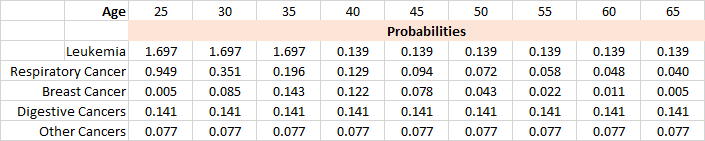

My esstimation suggests that, you have the greater risk of contracting blood cancer (Leukemia)  from what exposure you have gone through so far. 

Also, your future progeny has the probability of 1.2e-04 of having any kind of genetic defect, which, in my opinion, is very low.

My best wishes are with you. 